Right, so, firstly, using Poiseuille's law, $Q=\frac{\Delta p\pi D^4 }{128\mu \;L}$.

Secondly, ideal gas equation $\textrm{PV}=\textrm{mRT}$. Similarly, $P=\rho \text{ }\mathrm{RT}\to \rho =\frac{P}{\mathrm{RT}}=\frac{V}{m}$.

The volume of the cylinder changes as a function of time. Being a single-inlet system, the mass is also a function of time and the system is transient.

So, let $V\left(t\right)$ and $m\left(t\right)$be a function of time and the process be isothermal, then pressure inside the cylinder is given by ideal gas equation $P\left(t\right)=m\left(t\right)\frac{\textrm{RT}}{V\left(t\right)}$.

Identifying the system as a single inlet no outlet system, we obtain $Q=\frac{\text{dm}}{\text{dt}}$.

So, $\frac{\text{dm}}{\text{dt}}=\frac{\pi D^4 }{128\mu \text{ }L}\cdot \left(P_{\text{atm}} -\frac{m\left(t\right)}{V\left(t\right)}\text{RT}\right)$.

Here, $V\left(t\right)$is defined function of time.

Assume atmospheric conditions.

atm=101325;
R=8314/28;
T=298;
D=0.01;
mu=1.81e-5;
L=0.1;

Load up the symbolic lab.

syms t m1(t) m2(t) V(t) V1(t) V2(t)
V1(t)= 1 - 0.9/1*t;
V2(t)= 0.1;
Dm1 = diff(m1);
Dm2 = diff(m2);

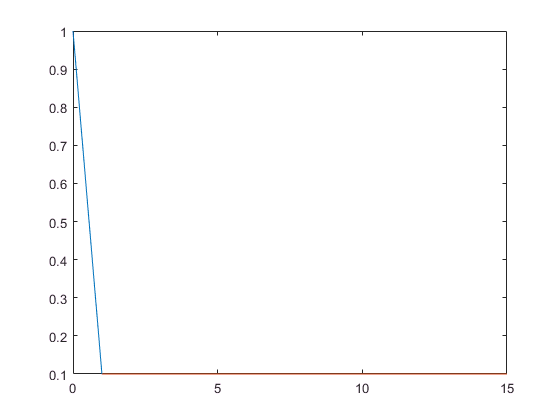

figure(1)
clf
fplot(V1,[0,1])
hold on
fplot(V2,[1,15])

Setup the equation.

eqn1 = Dm1-pi*D.^4/128/mu/L * (atm - m1*R*T/V1) == 0

$$eqn1(t) = \frac{\partial }{\partial t}m_{1}\left(t\right)-\frac{\pi \,\left(\frac{619393\,m_{1}\left(t\right)}{7\,\left(\frac{9\,t}{10}-1\right)}+101325\right)}{23168}=0$$

eqn2 = Dm2-pi*D.^4/128/mu/L * (atm - m2*R*T/V2) == 0

$$eqn2(t) = \frac{\partial }{\partial t}m_{2}\left(t\right)+\frac{\pi \,\left(\frac{6193930\,m_{2}\left(t\right)}{7}-101325\right)}{23168}=0$$

Boundary conditions.

cond1 = m1(0) == atm*V1(0)/R/T

$$cond1 = m_{1}\left(0\right)=\frac{709275}{619393}$$

cond2 = m2(1) == m1(1)

$$cond2 = m_{2}\left(1\right)=m_{1}\left(1\right)$$

Hit it: solve the equation.

[solm1, solm2] = dsolve([eqn1,eqn2],[cond1, cond2])

$$solm1 = -\frac{517623220800\,{\left(t-\frac{10}{9}\right)}^{\frac{3096965\,\pi }{729792}}}{619393\,{\left(-\frac{10}{9}\right)}^{\frac{3096965\,\pi }{729792}}\,\left(3096965\,\pi -729792\right)}-\frac{101325\,\pi \,{\left(t-\frac{10}{9}\right)}^{1-\frac{3096965\,\pi }{729792}}\,{\left(t-\frac{10}{9}\right)}^{\frac{3096965\,\pi }{729792}}}{23168\,\left(\frac{3096965\,\pi }{729792}-1\right)}$$

$$solm2 = \begin{array}{l} {\mathrm{e}}^{-\frac{3096965\,\pi \,t}{81088}}\,\left(\frac{141855\,{\mathrm{e}}^{\frac{3096965\,\pi \,t}{81088}}}{1238786}+\frac{51762322080\,{\mathrm{e}}^{\frac{3096965\,\pi }{81088}}\,\left(10\,{\left(-\frac{1}{9}\right)}^{\frac{3096965\,\pi }{729792}}-\sigma_{1}\right)}{619393\,\left(729792\,\sigma_{1}-3096965\,\pi \,\sigma_{1}\right)}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(-\frac{10}{9}\right)}^{\frac{3096965\,\pi }{729792}} \end{array}$$

The plotting section.

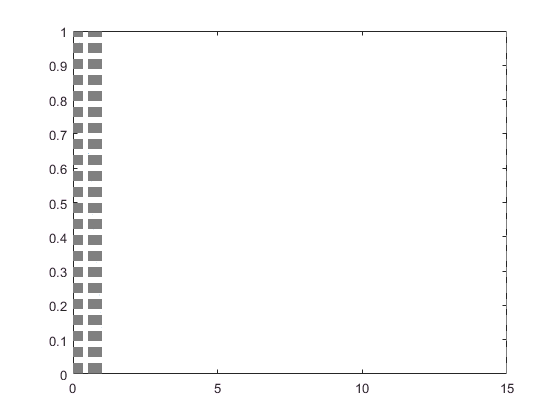

figure(2)
clf
fplot(solm1,[0,1])
hold on
fplot(solm2,[1,15])